clear
% func = @(x) sin(x);                 % testovaná funkce
func = @(x) (2.*x.^2)+(-5.*x)+4;
% func = @(x) (x.^3)+(2.*x.^2)+(-5.*x)+4;
% func = @(x) (-5.*x)+4;  

Vytvoříme N počet vzorků sínusovky z jedné periody a přidáme Gaussovský šum abychom získali trénovací data pro náš regresní model. 

from = -10;  
to = 10;  
% from = 0;  
% to = 2*pi; 

N =  20;                              % počet vzorků
x = from:((to-from)/(N-1)):to;           % vzorkovací čas
t = awgn(func(x),10);               % generátor naměřených dat     

Dále si připravíme testovací data v podobě nezkreslené sínusovky (bez Gaussova šumu).

x_c = from:((to-from)/((N*100)-1)):to;  % spojitý čas
t_c = func(x_c);                    % spojitý průběh

**M** odpovídá řádu polynomu, pro který budeme hledat koeficienty aproximačního polynomu.   

M = 2;                              % řád polynomu
max_iter = 2000;
q = 50;

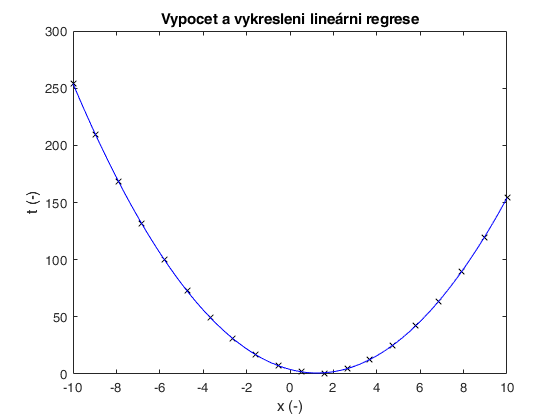

figure();
plot(x,t,'kx',x_c,t_c,'b');                     % vykreslení naměřených dat
title("Vypocet a vykresleni lineárni regrese");
xlabel("x (-)");
ylabel("t (-)")
hold on;

N = length(x);          % počet pozorování získaný z délky vektoru vstupních hodnot

syms w [1,M+1];                 % příprava koeficientů symbilicky (abych mohl spočítat obecný gradient funkce)
                                % dříve než budu koeficienty dosazovat, si spočítám gradient funkce, u které hledám minimum
                                % v našem případě to je funkce získaná metodou nejmenších čtverců. U této funkce budu hledat minimum na základně
                                % změny koeficientů, tzn. že budu parciálně derivovat tuto funkci každým koeficientem, čímž dostanu hodnotu
                                % obecně gradient funkce. Čili parciální derivace ve všech "směrech" koeficientů. Pokud tedy za koeficienty
                                % dosadím moje náhodné koeficienty, dostanu hodnotu jak moc a jakým směrem změnit tyto koeficienty, aby lépe
                                % aproximovali vstupní data.
                                
% Pokud bych si chtěl spočítat výstupní data pro náhodné koeficienty, popř. si z nich vykreslit graf nebo vypsat hodnotu MNČ: 
% t_aprox = Polynomial_evaluation(x,w_aprox); % vypočtení pro náhodný náhodný odhad koeficientů
% plot(x,t_aprox,'r') % zobrazení řešení pro náhodné koeficienty
% Least_squares_method(t_aprox,t);


y_x = sym(zeros(1,N));      % příprava pro vytvoření symbolického polynomu (koeficenty w budou zatím pouze symboly) 
for i = 1:N                 % pro všechny prvky x (v každém čase) 
    for j = 0:M             % vypočítej sumu přes daný řád polynomu
        y_x(i) = y_x(i) + ((w(j+1))*(x(i)^j));  % podle rovnice (x^j*w_j)
    end
end

E_w_sym = ((sum((y_x - t).^2))./2);     % obecně vyjádřené polynomy s koeficietny "w" použiji pro výpočet metody nejneších čtverců (čili pro funkci, kterou chci minimalizovat.) 
                                        % je nutné mít na paměti, že v této fázi jsou koeficienty stále jen symboly w a nikoliv čísla!                 
                                        
grad_sym = sym(zeros(1,M+1));      % příprava pro vytvoření symbolického polynomu (koeficenty w budou zatím pouze symboly) 
for i = 1:(M+1)                         % v tuto chvíli přichází na řadu spočítání parciálních derivací podle všech koeficientů 
    grad_sym(i) = diff(E_w_sym,w(i));   % v podstatě jen derivuji funkci MNČ podle w1, potom w2, w3 .. atd, takže dostávám M rovnic, kde každá je dervována jedním koeficientem 
end   
 

w_aprox = rand(M+1,1)*10;       % vytvoření náhodných koeficientů, ze kterých budu ve výpočtu vycházet a postupně je měnit

t_w = Polynomial_evaluation(x,w_aprox); % vypočtení pro náhodný náhodný odhad koeficientů
plot(x,t_w,'r') % zobrazení řešení pro náhodné koeficienty
Least_squares_method(t_w,t)


iter = max_iter;            % tahle matlab funkce kterou tady tvořím mi vrátí počet iterací, za které našla řešení, proto do něj teď uložím maximální počet iterací a pokud to zvládne dřív, tak se proměnná přepíše na daný počet

for i = 1:max_iter          % jelikož jsou připraveny gradienty pro celou funcki zíkanou MNČ, tak mohu přistoupit k samotnému výpočtu

    grad = double(subs(grad_sym,w,w_aprox'))';      % ten je velmi jednoduchý. Prostě dosadím náhodně získané koeficienty do spočtených gradientů a tím zjistím hodnoty spádu pro dané koeficienty v daném směru
     
    w_aprox_i(i,:) = w_aprox;
     
    w_aprox = w_aprox - (grad.*0.00001);            % tuto hodnotu přenásobím koeficientem učení a následně odečítám od hodnoty mých náhodných koeficientů. Díky tomu získám koeficienty jiné, které však díky odečítání od směru gradientu by měl mířit k minimu funkce    
 
    
    t_w = Polynomial_evaluation(x,w_aprox);         % nyní si spočítám výstup mé nové proximované funcke 
    [E_w,e] = Least_squares_method(t_w,t);          % vypočítám jak moc dobře aproximuje zadané body pomocí MNČ
    E_w_i(i) = E_w;
    
    if (mod(i,100) == 0)
        plot(x,t_w);
    end
    
    if E_w < q          % a porovnám ho s tolerancí, pokud by byl pod tolerancí, mohu hodnotu vrátit
        iter = i;
        break;
    end
end


t_w = Polynomial_evaluation(x,w_aprox); % vypočtení pro náhodný náhodný odhad koeficientů

plot(x,t_w,'m') % zobrazení řešení pro náhodné koeficienty

hold off;
plot(1:iter,E_w_i);